%% 
% 1. generate random firing of neuron using "rand f"
% 2. Define all the parameters
%3. create jansen ODE function which will be used for solving ODE's
% 4. Create sigmoid function
% 5. Use 3 and 4 in the main code

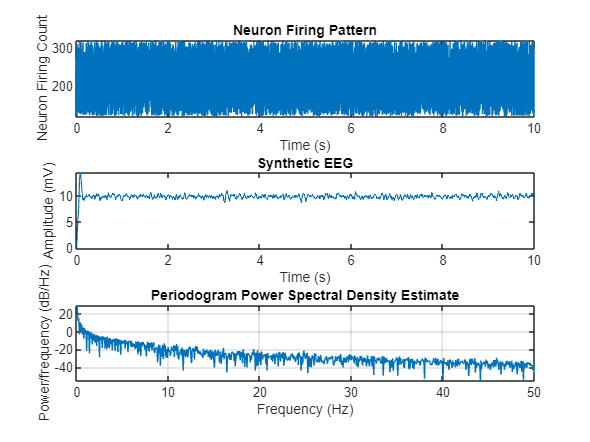

y0 = zeros(6,1);
dt = 0.001; %step size in second
T = 10; %total duration
clock = 0:dt:T;
rng(10) %for reproducibility
p = 200*rand(size(clock))+120; %random firing of neuron
figure()
subplot(3,1,1)
plot(clock,p)
xlabel('Time (s)'); ylabel('Neuron Firing Count');
title('Neuron Firing Pattern')
%parameter definition
Params = struct('A',3.25,'B',17.6,'a',100,'b',50,'e0',2.5, ...
 'C',108,'r',0.56,'v0',6);
%solution
[t,y] = ode45(@(t,y) JansenSingleODEs(t,y,Params,p,clock),clock,y0);
subplot(3,1,2)
plot(t(2:end),y(2:end,2)-y(2:end,3),'LineWidth',0.8);
xlabel('Time (s)'); ylabel('Amplitude (mV)')
title('Synthetic EEG')
subplot(3,1,3)
periodogram(y(:,2)-y(:,3),[],[],1/dt)
xlim([0 50])

function ydot = JansenSingleODEs(t,y,Params,p,clock)
p = interp1(clock,p,t);
A = Params.A; a = Params.a; B = Params.B; b = Params.b;
C1 = Params.C; C2 = 0.8*C1; C3 = C1/4; C4 = C3;
ydot = zeros(size(y));
ydot(1) = y(4);
ydot(4) = A*a*Sigm(y(2)-y(3),Params) - 2*a*y(4) - a^2*y(1);
ydot(2) = y(5);
ydot(5) = A*a*(p + C2*Sigm(C1*y(1),Params)) - 2*a*y(5) - a^2*y(2);
ydot(3) = y(6);
ydot(6) = B*b*C4*Sigm(C3*y(1),Params) - 2*b*y(6) - b^2*y(3);
end
function out = Sigm(y,Params)
e0 = Params.e0;
v0 = Params.v0;
r = Params.r;
out = 2*e0/(1+exp(r*(v0-y)));
end